# Hand Movement Classification Based on EMG Signals Using Machine Learning

**Objective**

The goal of this analysis is to develop a classifier to identify type of movement from electromyogram (EMG) signal for prosthetics development. EMG is the electrcal activity of muscle in rsesponse to a nerve's stimulation of the muscle.

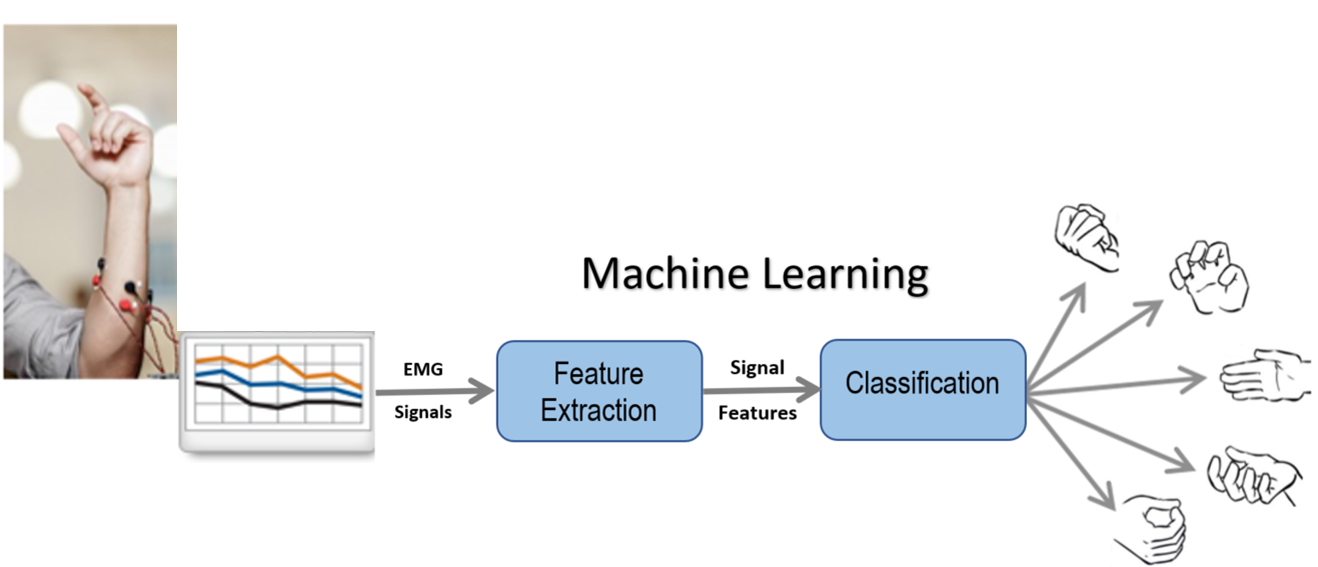

We will process EMG signals with known actions, then train a classification algorithm to make predictions given new electrode readings.  

**EMG Signal**

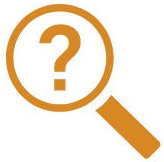

- Can we increase the EMG signal amplitude voluntarily?

- What is the physiological phenomenon behind EMG signal amplitude?

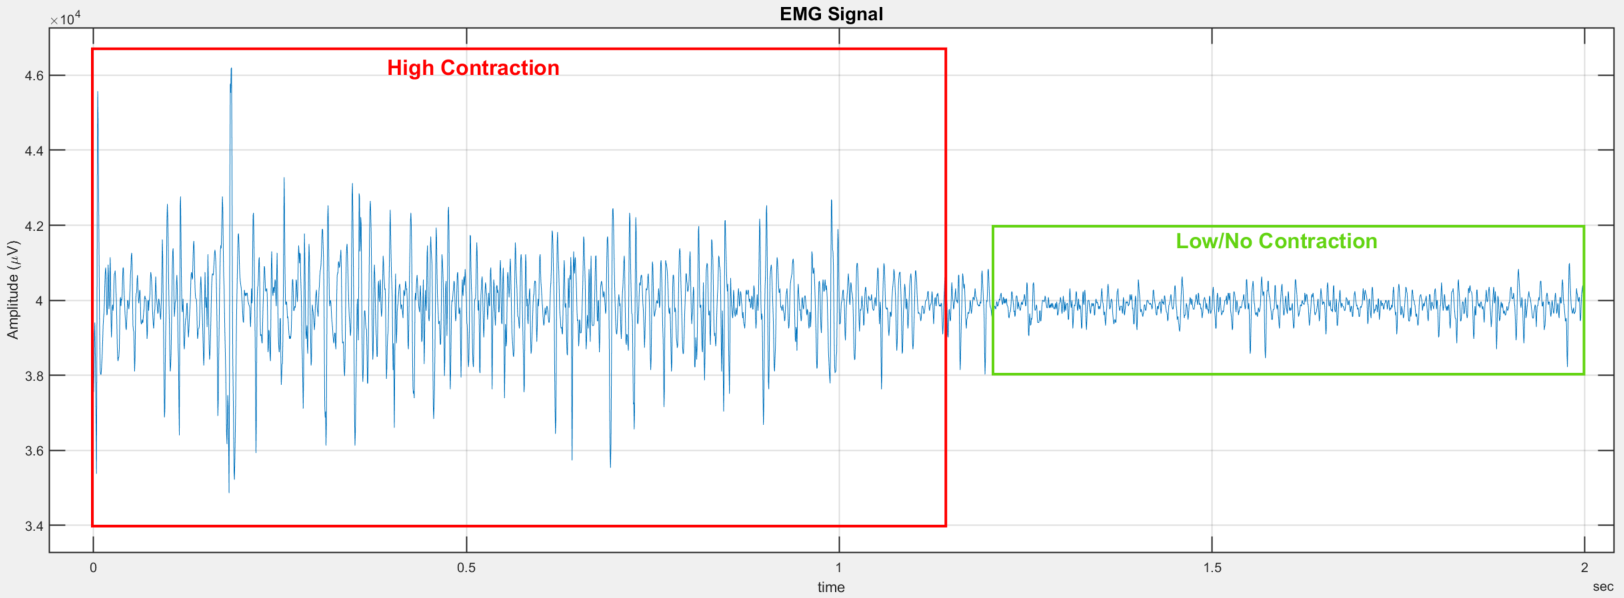

The EMG signal is an electrical signal that measures currents generated in muscles during its contraction in response to neural inputs. 

Muscle contraction results in body movements. The **research question** here is if we can determine body movements from EMG signals.

## 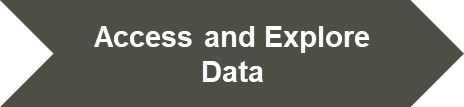

## 1. Access and Explore

###     1.1. Initialize Parameters

clear; clc; close all;
cp = openProject("EMG_Demo.prj");

fs = 1800;          % Sampling frequency (Hz)
dt = 1/fs;          % Sampling period (s)
nelectrodes = 8;    % Number of electrodes
ET = 2.85;          % Experiment time for each action

###     1.2. Import Data

First, we need to import the data from each of the different files into one table. A convenient way to do this is with `datastore`. Datastores allow you to point at a collection of files, specify the formatting, and then read in all or a portion of the data as needed.

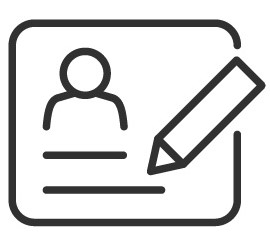 [**datastore**](https://www.mathworks.com/help/matlab/datastore.html)

trainds = datastore(fullfile(cp.RootFolder, 'Data\TrainingData\*.csv'));
trainds.SelectedFormats{9} = '%C'; % Convert labels to categorical

Read all of the data into one table and create a time vector for plotting.

TrainData = readall(trainds);
t = seconds(0:dt:dt*(height(TrainData)-1))';
preview(trainds)

ans = 8×9 table
    rawDataOut1    rawDataOut2    rawDataOut3    rawDataOut4    rawDataOut5    rawDataOut6    rawDataOut7    rawDataOut8      Action  
    ___________    ___________    ___________    ___________    ___________    ___________    ___________    ___________    __________
       36838          37549          38656          38854          38616          38933          38893          59486       Chuck Grip
       40395          38024          38854          39723          39644          39763          39684          56561       Chuck Grip
       41344          39091          38893          40118          40395          40158          39723          49407       Chuck Grip
   

###     1.3. Visualize Data

Let's visualize the signals, colored by action, in the grouped scatter plots below. Using the the following controls, electrodes can be selected and EMG signals recorded from the elecrtodes can be displayed. 

First, select the electrodes:

e1=true;   e2=false;   e3=true;   e4=false;   e5=false;   e6=false;   e7=false;   e8=true;


The, plot the EMG from selected electrodes:

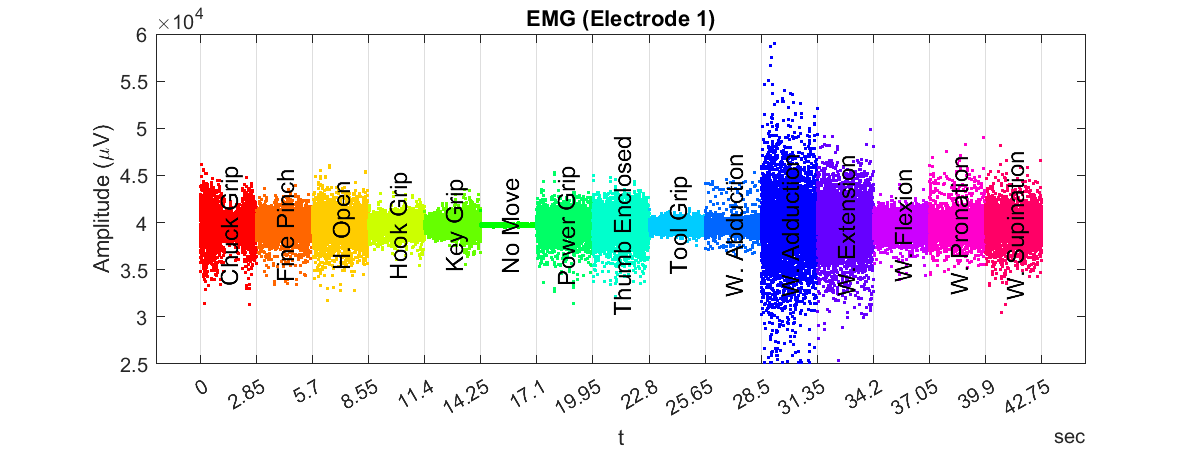

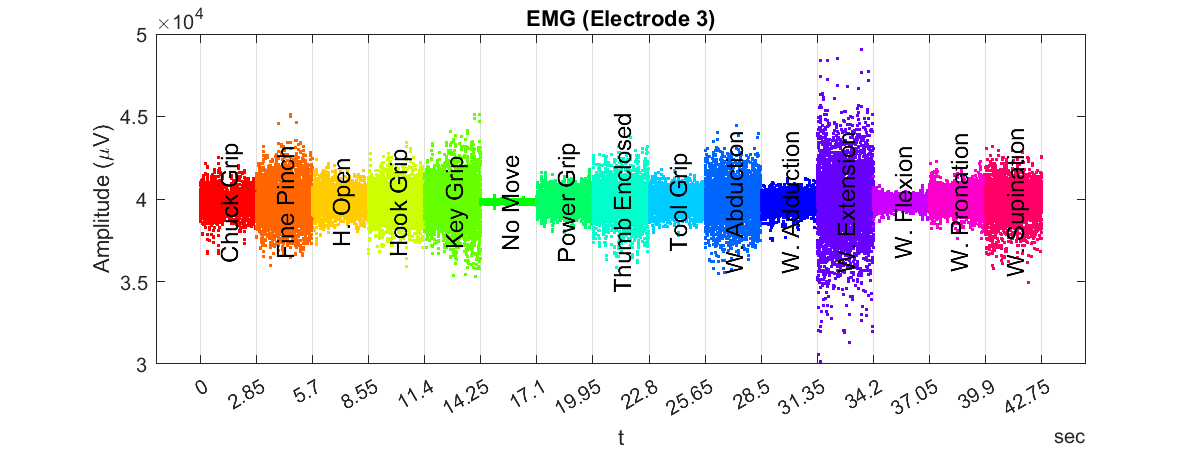

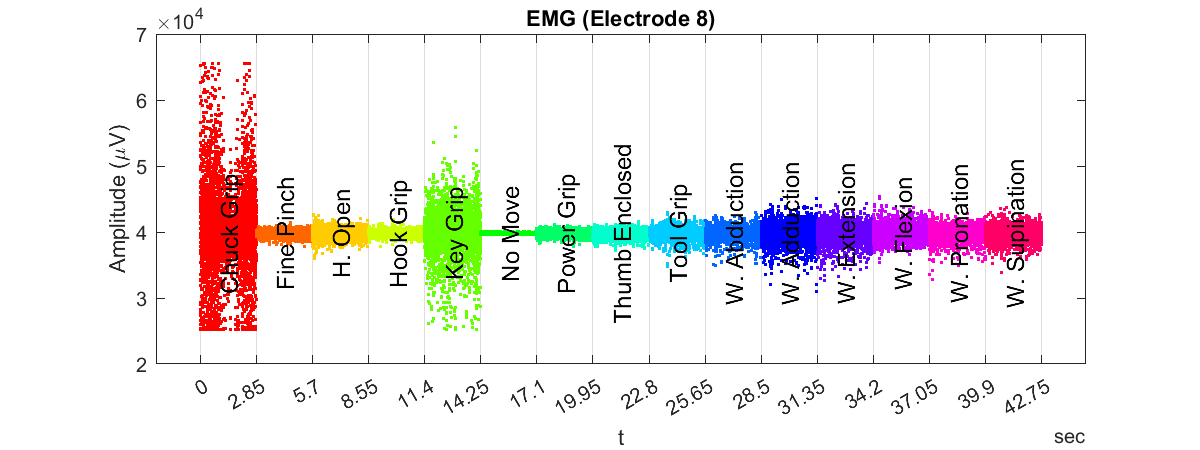

 

electrodes = find([e1,e2,e3,e4,e5,e6,e7,e8]);
plot_EMG_actions(ET, TrainData, t, electrodes)

We can also take a look at all of the channels for a single action using [`stackedplot`](matlab: web(fullfile(docroot, 'matlab/ref/stackedplot.html'))).

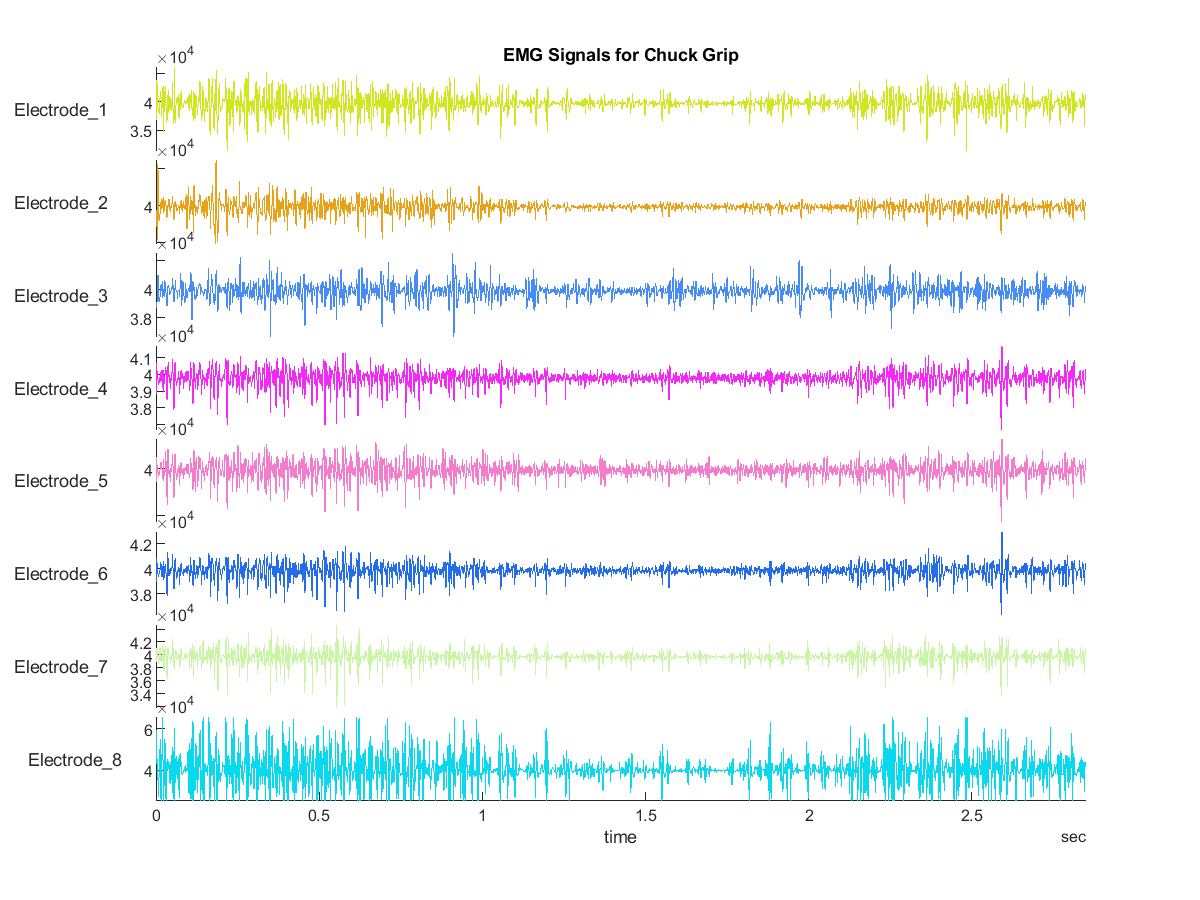

ActionToPlot = "Chuck Grip";

plot_EMG_channels(TrainData, t, ActionToPlot)

## 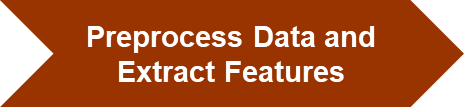

## 2. Feature Extraction

Feature extraction can help the classification algorithms do a better job by smoothing, transforming, or applying statistics to the original signal that are better indicators of what is happening in the data. Examining the grouped scatter plot, it appears that the variance, range, and mean of small segments might help differentiate between classes.

We also need to consider the **window length** when calculating statistics. 

 Does the window size has any effect on the accuracy of the overall performance system?

TimeWindow = 50;    % Processing time window in msec
blocksize = TimeWindow/1000*fs;       % The number of samples in the processing time window

###     2.1. Basic Statistics

Let's explore the basic statistics such as **max**, **mean**, **min**, and **var** extracted from EMG data. Use `blockproc` to apply the functions to the blocks and then append the known action.

 [**blockproc**](https://www.mathworks.com/help/images/ref/blockproc.html?searchHighlight=blockproc&s_tid=srchtitle_blockproc_1)

statfuns = @(x)[max(x) mean(x) min(x) var(x)];
features = {'max';'mean';'min';'var'};
TrainDataStats = extract_features(TrainData, features, statfuns, nelectrodes, blocksize);

The number of features is 32.
There are 57 cases for each of 15 actions.


Table_Head = 8×33 table
    max1     mean1    min1        var1       max2     mean2    min2        var2       max3     mean3    min3        var3       max4     mean4    min4        var4       max5     mean5    min5        var5       max6     mean6    min6        var6       max7     mean7    min7        var7       max8     mean8    min8        var8         Action  
    _____    _____    _____

 Which one of these four features is more important in EMG classification?

## 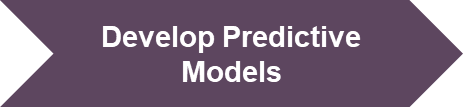

## 3. Classification

In order to train the classifier, we will use the Classification Learner App. This is an interactive environment where you can experiment with many different machine learning algorithms and evaluate how well they perform.

  [`classificationLearner`](https://www.mathworks.com/help/stats/classificationlearner-app.html?searchHighlight=classificationlearner&s_tid=srchtitle_classificationlearner_1)

###     3.1. Train Classifier

We can use the generated code from the classification learner to calculate the validation accuracy. 

[classifier, validationAccuracy] = trainEMGClassifier(TrainDataStats);
disp(['The training accuracy is ', num2str(validationAccuracy * 100) ,'%'])

The training accuracy is 98.1221%


###     3.2. Make Predictions on Test Set

Now that we have a trained classifier, it can be used to make predictions on the independent test set from another experiment.

Apply all of the same preprocessing steps to the new data.

testds = datastore(fullfile(cp.RootFolder, 'Data\TestingData\*.csv'));
testds.SelectedFormats{9} = '%C'; TestData = readall(testds);

TestDataStats = extract_features(TestData, features, statfuns, nelectrodes, blocksize);

The number of features is 32.
There are 57 cases for each of 15 actions.


Table_Head = 8×33 table
    max1     mean1    min1        var1       max2     mean2    min2        var2       max3     mean3    min3        var3       max4     mean4    min4        var4       max5     mean5    min5        var5       max6     mean6    min6        var6       max7     mean7    min7        var7       max8     mean8    min8        var8         Action  
    _____    _____    _____

Then, make prediction and compare to known results.

[PredictedAction,~] = predict(classifier.ClassificationEnsemble, TestDataStats);
disp(['The overall accuracy for all classes is ', num2str(nnz(PredictedAction==TestDataStats.Action)./numel(PredictedAction)*100),'%'])

The overall accuracy for all classes is 81.1696%


Now, let's take a look at individual classes:

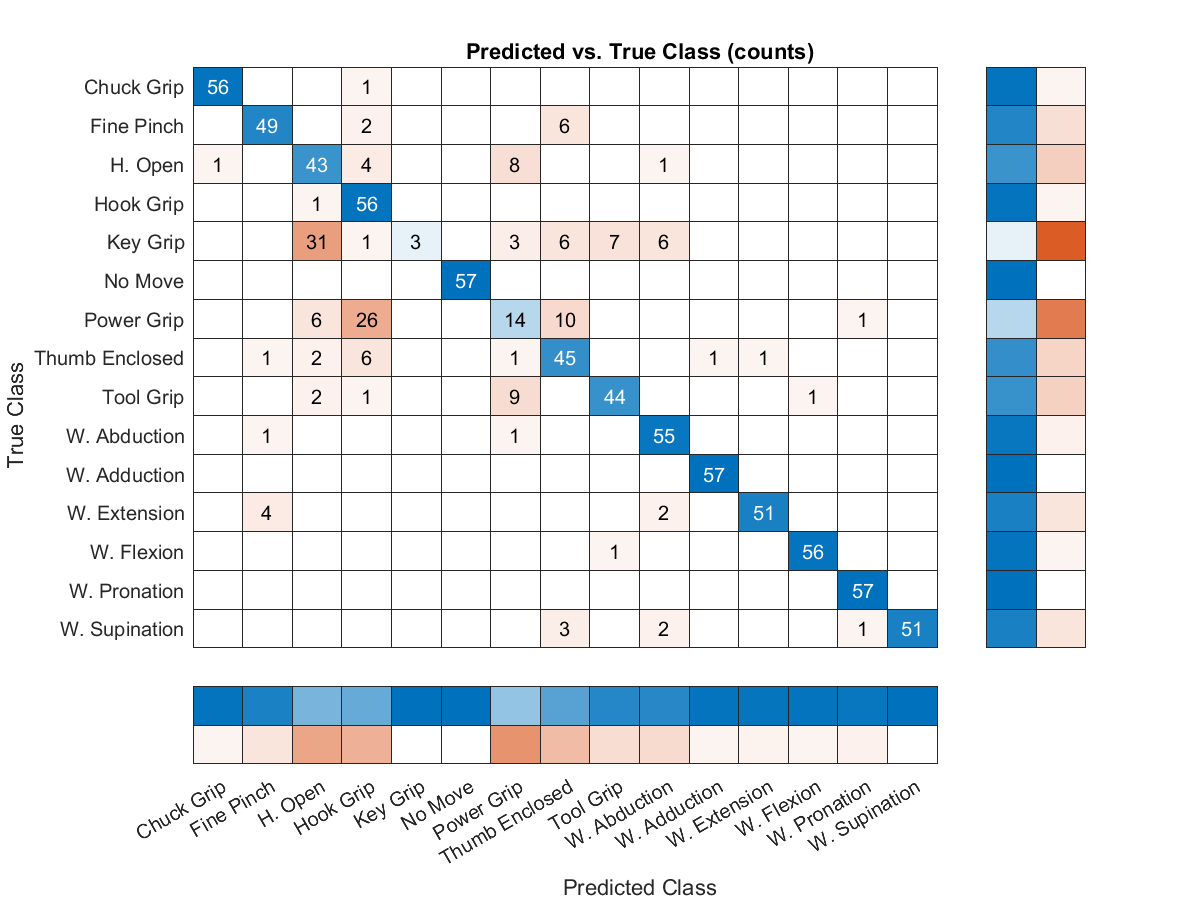

cm = confusionchart(TestDataStats.Action, PredictedAction, ...
    'ColumnSummary','column-normalized', ...
    'RowSummary','row-normalized', ...
    'Title',"Predicted vs. True Class (counts)");

###     3.3. Model Refinement: Predictor Importance

Which predictors are the most important to the model? The `predictorImportance` metric will tell us how much more error there is if that predictor was to be removed.

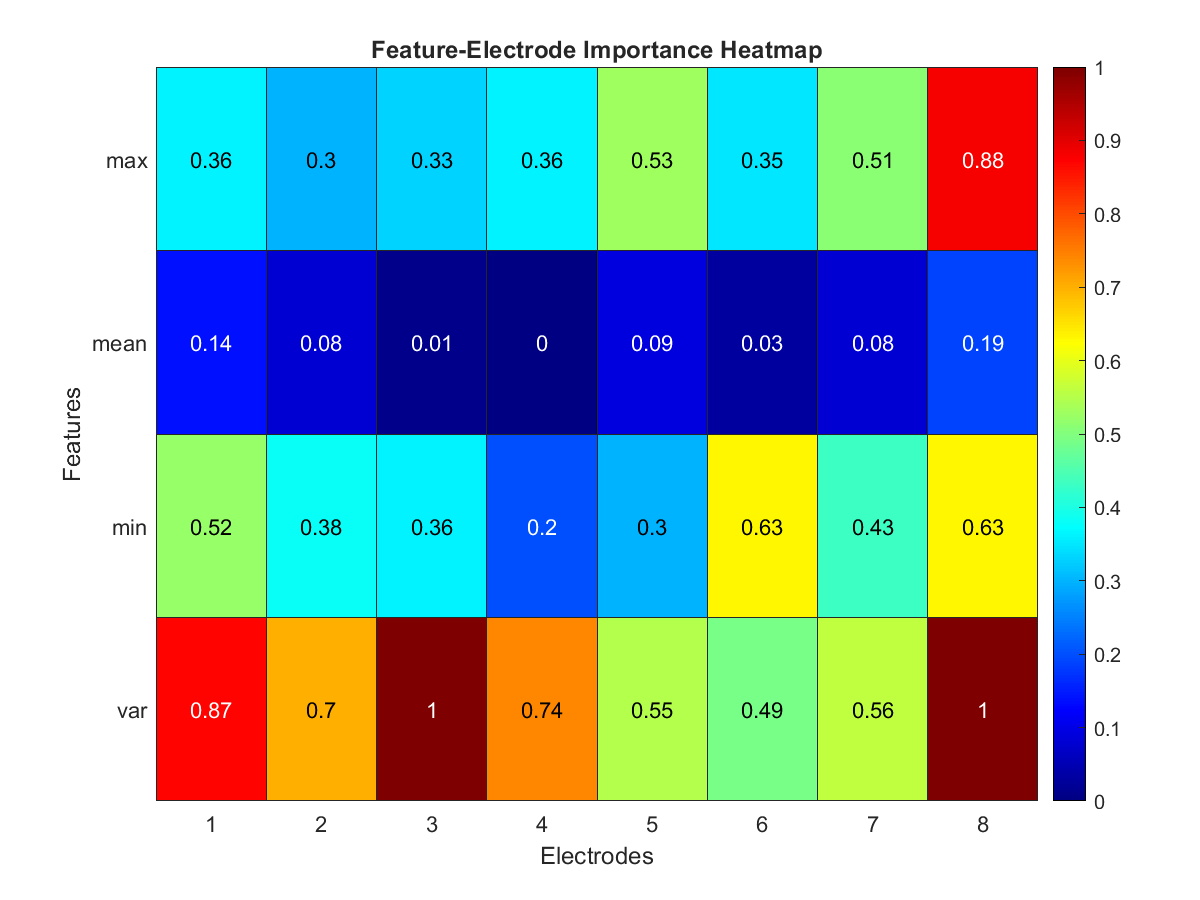

predimp = predictorImportance(classifier.ClassificationEnsemble);
heatmap(reshape(round(normalize(predimp,'range'),2), numel(features), nelectrodes),...
    'Colormap', jet, ...
    'FontSize',11,...
    'Ydata', features, ...
    'YLabel','Features',...
    'XLabel','Electrodes',...
    'Title','Feature-Electrode Importance Heatmap');

###     3.4. Can This Be Improved?

The above accuracy leaves a little to be desired. There are numerous things to be considered.

- Did we choose a right window size?

- Did we choose the right features?

- Did we have the right classifier?

- Are the electrodes in the right place?

- Where is the confusion?

- Is there any more information we know that can be used?

- ...

You can answer to many questions using MATLAB and to improve your classification accuracy.

For example: 

- Let's try another window size ...

- We will see advanced features later.

## 

## 4. Advanced Features

For signals that are statistically similar, it is no longer sufficient to rely on simple statistics to differentiate between the signals. This is when signal processing can play a key role. Let's first remove the DC offset and rectify the raw signal, which are common tasks in EMG processing. 

This can be done with signalanalyzer app.

  [`signalAnalyzer`](https://www.mathworks.com/help/signal/ref/signalanalyzer-app.html?searchHighlight=signal%20analyzer%20app&s_tid=srchtitle_signal%20analyzer%20app_1)

**Signal Analyzer**

Where do we find features for machine learning? There are many possible waveform parameters that can be explored and extracted. Let's use the [Signal Analyzer App](matlab: signalAnalyzer) to visualize and explore the differences between a few signals to get some ideas for differentiating between the various actions.

Open the Signal Analyzer App from the toolstrip or with the following command or from the App tab for a sample extracted EMG signal (EMG_Chuck_Grip).

EMG_Chuck_Grip = TrainData{TrainData.Action == 'Chuck Grip',1};
% signalAnalyzer

### **    4.1. Remove DC Offset**

Use [`detrend`](matlab: web(fullfile(docroot, 'matlab/ref/detrend.html'))) to remove the DC offset from the EMG signal in preparation for signal processing.

data_DC = detrend(TrainData{:,1:end-1});

### **    4.2. Full-Wave Rectification**

Half- or full-wave rectification is a common step in processing EMG signals. We will do this by taking the absolute value of the signal. 

rec_data = abs(data_DC);

Then visualize the rectified signal below.

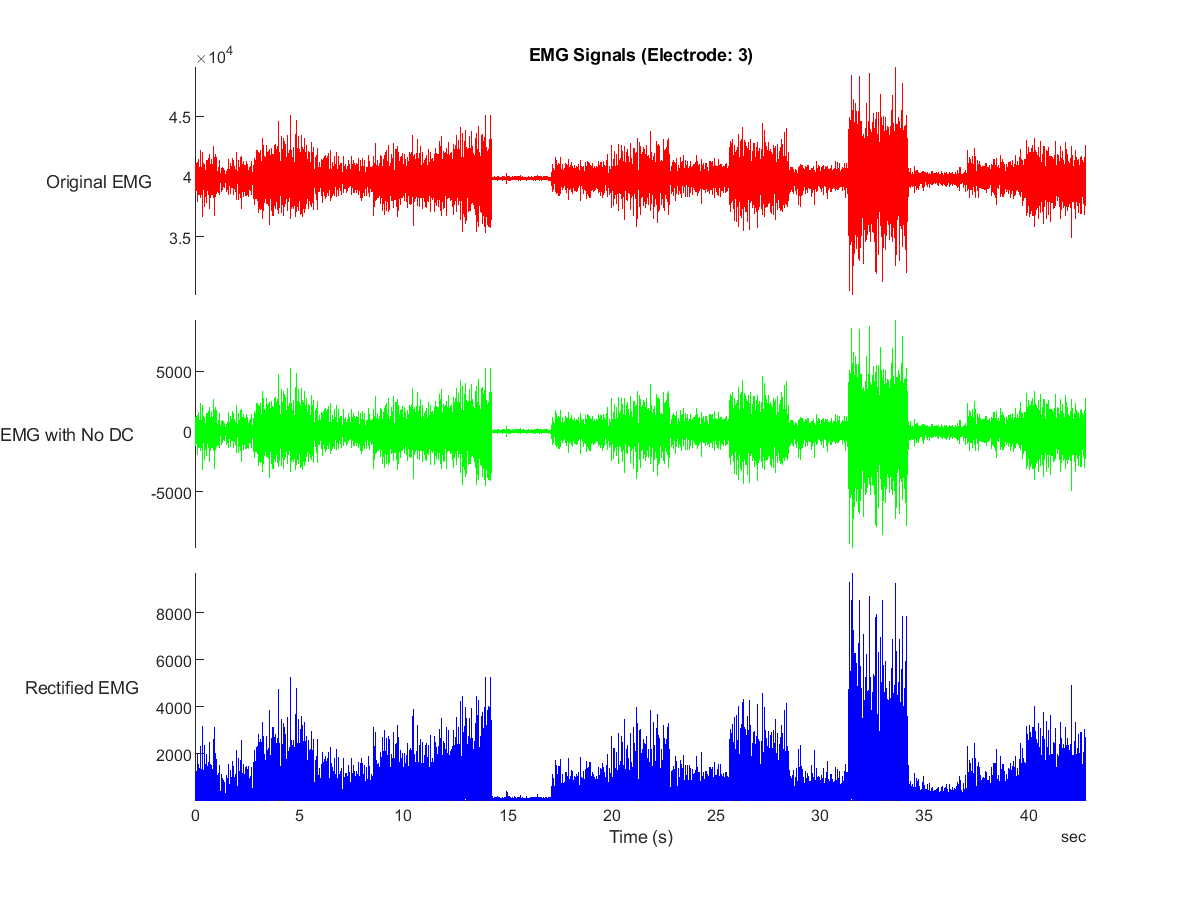

electrode = 3;
data = [TrainData{:,electrode}, data_DC(:,electrode), rec_data(:,electrode)];
EMG_lables = {'Original EMG   ', 'EMG with No DC   ','Rectified EMG   '};

plot_EMG_features(t, data, EMG_lables, electrode)

###      4.3. Linear Envelope

Another common approach to processing EMG signals is to take the linear envelope. Let's look at two methods for finding the linear envelope: using a low pass filter, and using RMS.

**Option 1 - Low Pass Filter **

Let's first try out the Filter Designer App to apply a low-pass filter to the rectified signal to obtain the signal envelope.

env1 = filter(LPFilter,rec_data);

**Option 2 - RMS Envelope**

A common approach to obtaining the linear envelope is via RMS. 

[env2,~] = envelope(rec_data,fs/5,'rms');

**Option 3 - Peak Envelope**

A common approach to obtaining the linear envelope is via RMS. 

[env3,~] = envelope(rec_data,fs/5,'peak');

**Plot Envelopes and and Compare**

 Which envelope detection is better?

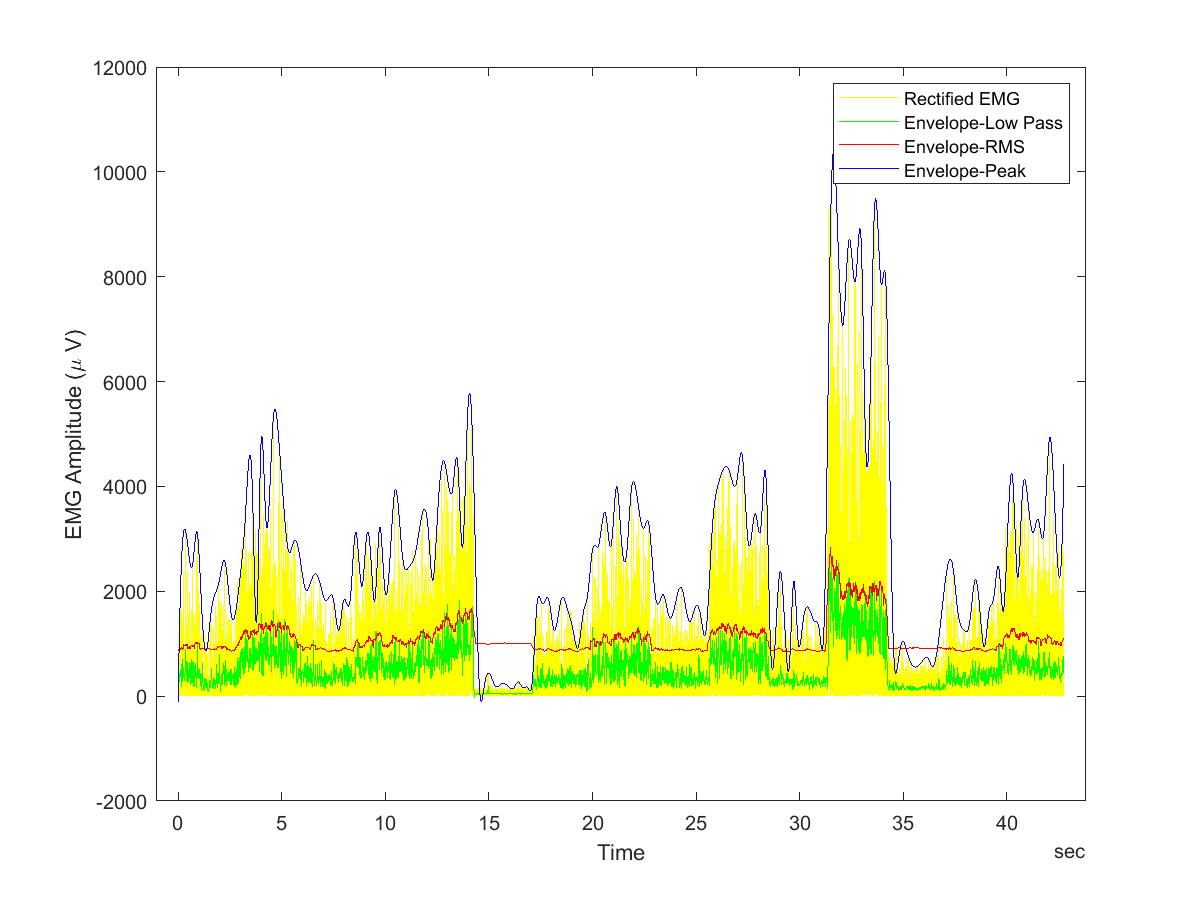

plot_envelopes(t, rec_data, env1, env2, env3, electrode)

###     4.4. Frequeny Domain Features

Let's consider the frequency domain. Some other common parameters used in EMG analysis are 

- Amplitude Parameters - peak EMG value, mean EMG value, area under the EMG amplitude (mathematical integral)

- Frequency Parameters - peak power, total power (area under the spectrum curve), mean frequency, median frequency

**Total Power Calculation**

Let's compare the total power for two actions and get the total power as a feature. 

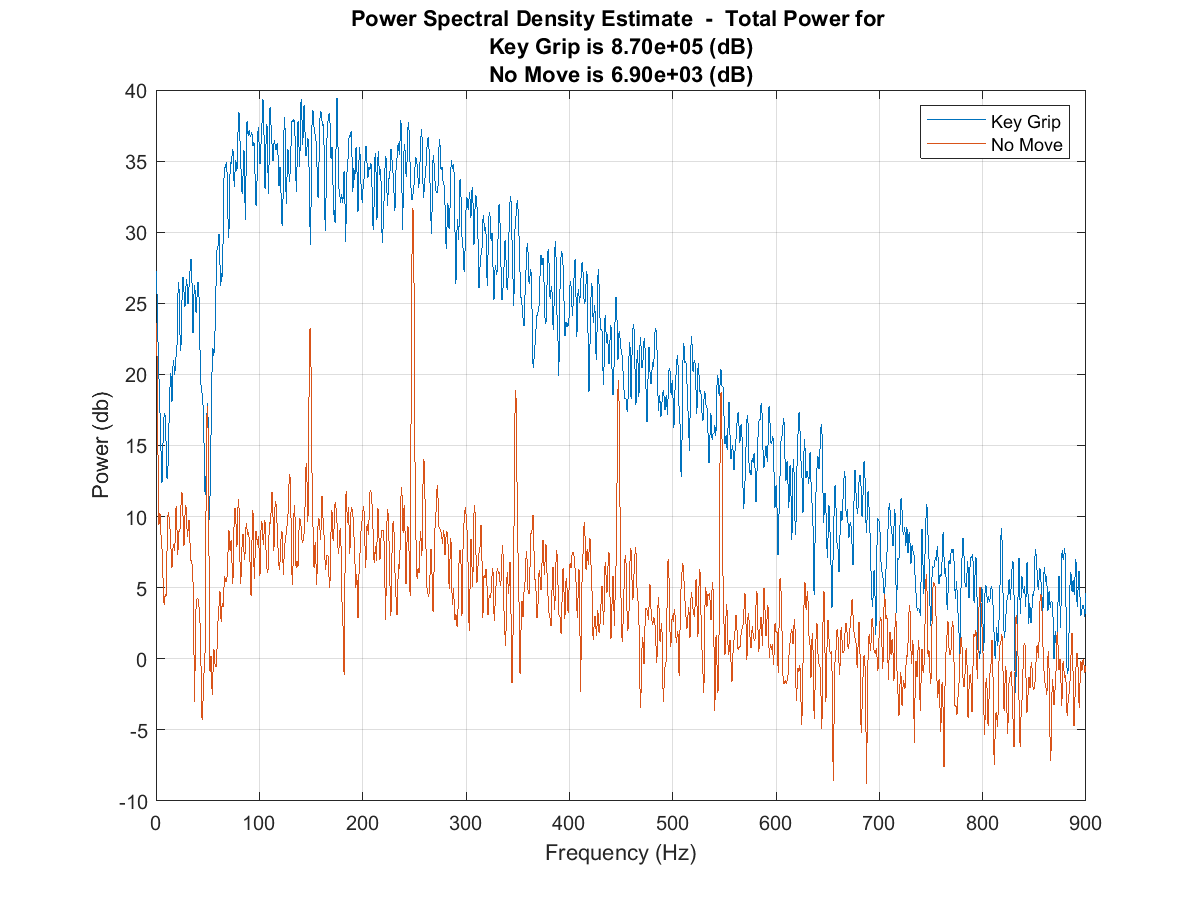

Action_1 = "Key Grip"; Action_2 = "No Move";
plot_powers(data_DC, TrainData, Action_1, Action_2, fs);

## 

## 5. Classification

Now that we've looked at more specific features, let's train our machine learning model. There are many features from time and frequency domain we can exploit as predictors for the EMG signal. For now, let's use the **envelope** we calculated before, **signal variance**, and **total power** under the spectrum curve.  Open [generateFeatures](matlab: edit generateFeatures) to examine the code.

funs = @(x)generateSignalFeatures(x,fs);
traindataSP = blockproc(TrainData{:,1:nelectrodes},[blocksize nelectrodes],@(block)funs(block.data),'UseParallel',false);
traindataSP = array2table(traindataSP);
features = {'var';'env';'tpwr'}; 
traindataSP.Properties.VariableNames = makeVariableNames(features, nelectrodes);
traindataSP.Action = TrainData.Action(1:blocksize:end);

Now that we have our features for training, the next step is to choose a machine learning algorithm. Which type of classifier will work best in this case? We will use the Classification Learner App to explore various algorithms until we find one that yields satisfactory results.

`classificationLearner`

An added benefit in using the Classification Learner is that it can generate the MATLAB code to retrain the model or incorporate new data.  Below, we use the generated code from the classification learner to calculate the validation accuracy.  In this case, we use 5-fold cross-validation.

[classifier, validationAccuracy] = trainSPClassifier(traindataSP);

disp(['Accuracy is ', num2str(validationAccuracy * 100) ,'%'])

Accuracy is 96.4912%


###     5.1. Make Predictions on Test Set

Now that we have a trained classifier, it can be used to make predictions on the independent test set from another experiment.

Apply all of the same preprocessing steps to the new data.

testds = datastore(fullfile(cp.RootFolder, 'Data\TestingData\*.csv'));
testds.SelectedFormats{9} = '%C';
TestData = readall(testds);
testdataSP = blockproc(TestData{:,1:nelectrodes},[blocksize nelectrodes],@(block)funs(block.data),'UseParallel',false);

Then use the classifier to make predictions and compare to known results.

[PredictedAction,score] = predict(classifier.ClassificationEnsemble,testdataSP);
disp("The overall accuracy for all classes is " + nnz(PredictedAction==TestData.Action(1:blocksize:end))./numel(PredictedAction)*100 + "%")

The overall accuracy for all classes is 81.4035%


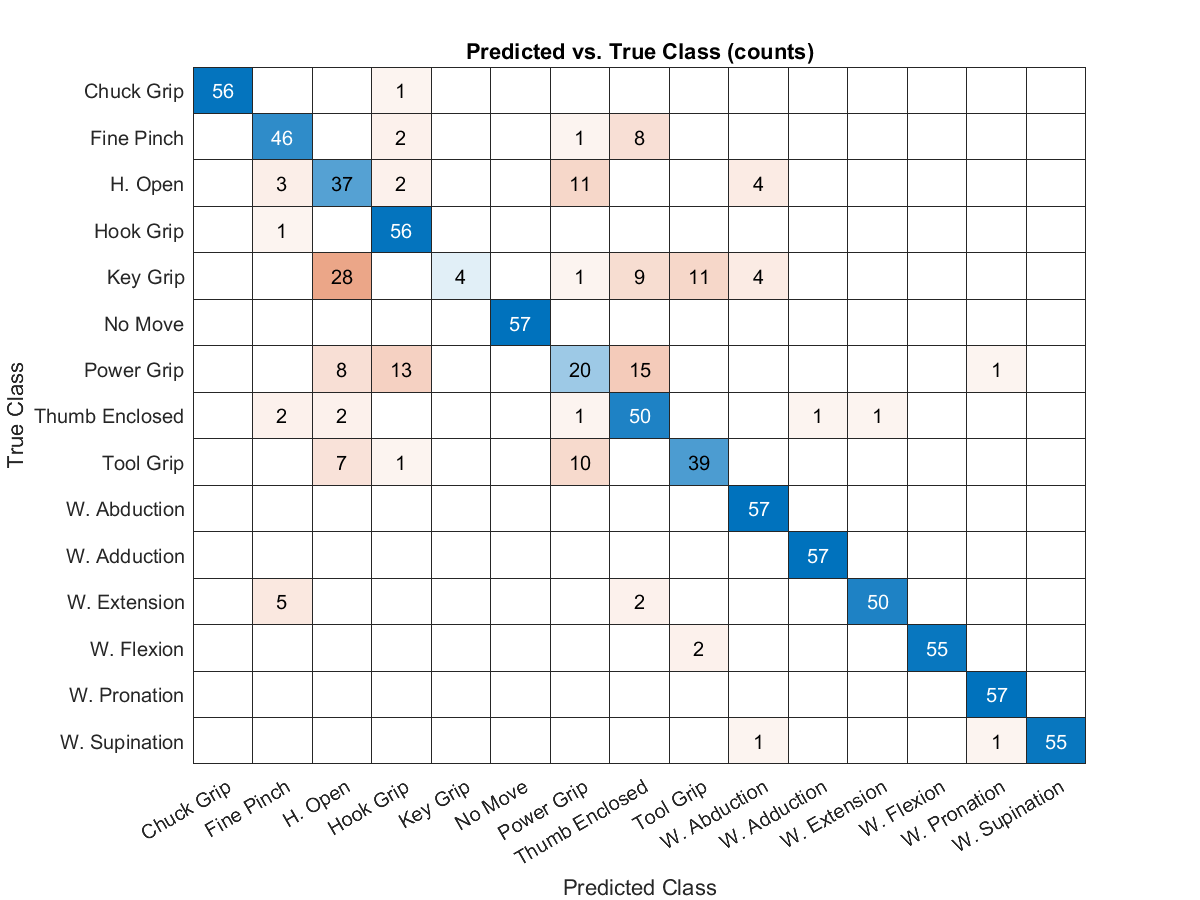

confusionchart(TestData.Action(1:blocksize:end), PredictedAction);
title("Predicted vs. True Class (counts)")

###     5.2.  Predictor Importance

Which predictors are the most important to the model? The `predictorImportance` metric tells us how the error would change if that predictor were removed.

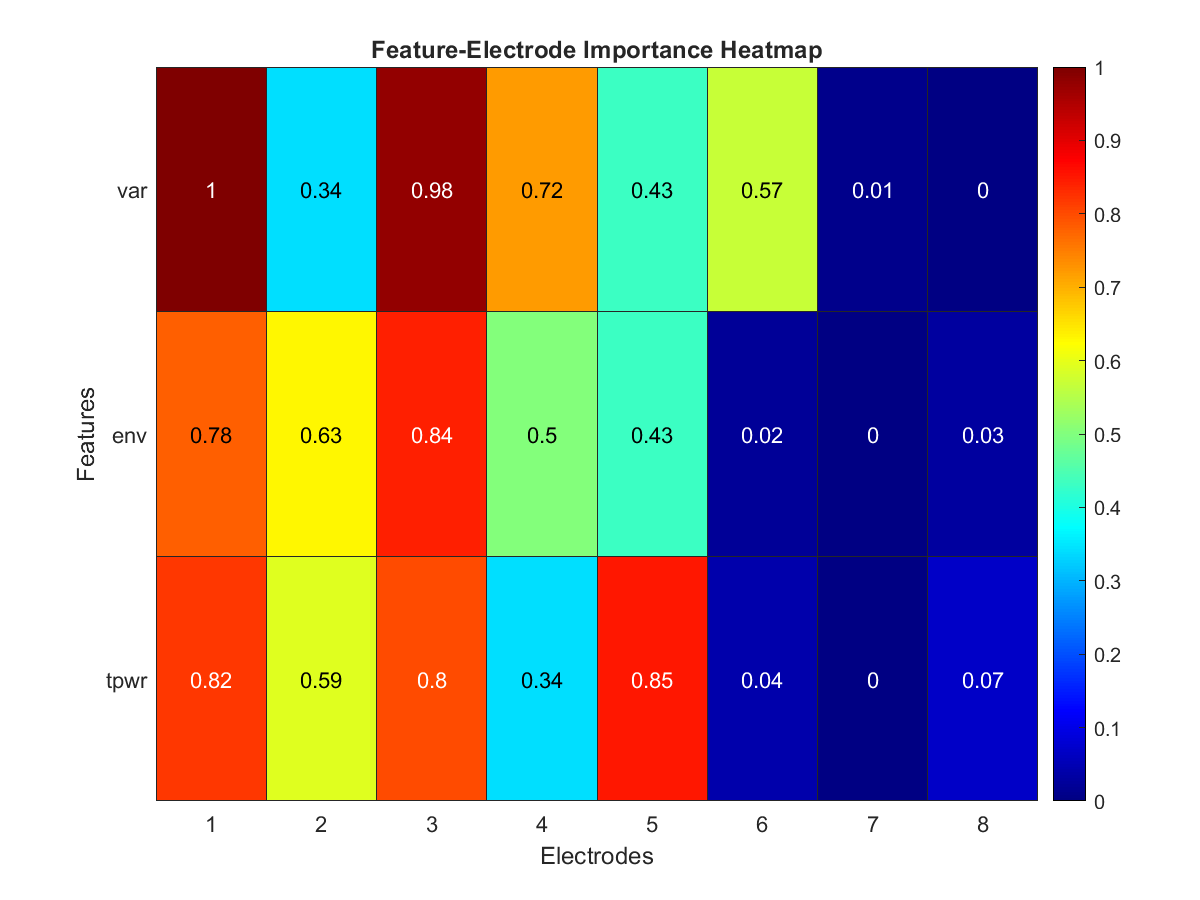

predimp = predictorImportance(classifier.ClassificationEnsemble);
heatmap(reshape(round(normalize(predimp,'range'),2), numel(features), nelectrodes),...
    'Colormap', jet, ...
    'FontSize',11,...
    'Ydata', features, ...
    'YLabel','Features',...
    'XLabel','Electrodes',...
    'Title','Feature-Electrode Importance Heatmap');

###     5.3. Use the Classifier to Test New Data

Let's package up the classifier into a function that takes raw signal data from our 8 channels and outputs a classification for that chunk of signal.

x = TestData{1:57,1:nelectrodes};
Predicted_Action = classifyEMGSignal(x,fs)

Predicted_Action = 'Chuck Grip'

`Helper Functions`

function varnames = createVariableNames(funs,n)
    % Make variable names with functions in them
    
    assert(n<10,'n must be less than 10');
    varnames = strcat(repmat(funs,n,1),repelem(cellstr(('1':num2str(n))'),numel(funs),1));
end


function plot_EMG_actions(ET, TrainData, t, electrodes)
    Actions = categories(TrainData.Action);
    nActions = numel(Actions);
    ET_s = seconds(ET);
    
    for n=1:length(electrodes)
        x0 = ET_s/2:ET_s:max(t); y0=mean(TrainData{:,electrodes(n)})*ones(size(x0));
        figure('Renderer', 'painters', 'Position', [0 0 1000 300]);
        gscatter(t,TrainData{:,electrodes(n)},TrainData.Action)
        legend off; title("EMG (Electrode " + num2str(electrodes(n)) + ")")
        ylabel('Amplitude (\muV)'); set(gca, 'YGrid', 'off', 'XGrid', 'on'); 
        xticks(seconds(0:ET:nActions*ET)); 
        text(x0,y0,Actions,'fontsize', 12,'rotation', 90,'HorizontalAlignment','center');
    end
end

function plot_EMG_channels(TrainData, t, ActionToPlot)

    figure('Renderer', 'painters', 'Position', [0 0 1200 600])
    TrainDataTime = table2timetable(TrainData,'RowTimes',t);
    ind = TrainDataTime.Action == ActionToPlot;
    data = TrainDataTime{ind, 1:8};
    ti = TrainDataTime.Time(ind);
    S = stackedplot(ti,data,'DisplayLabels',"Electrode_" + (1:8)+"    ");
    for n=1:8
        S.LineProperties(n).Color = rand(1,3);
    end
    xlabel('time')
    title("EMG Signals for "+ num2str(ActionToPlot))
end


function TrainDataStats = extract_features(TrainData, features, statfuns, nelectrodes, blocksize)

    varnames = createVariableNames(features, nelectrodes);
    % Apply and append action
    TrainDataStats = blockproc(TrainData{:,1:nelectrodes},[blocksize 1],@(block)statfuns(block.data));
    TrainDataStats = array2table(TrainDataStats);
    TrainDataStats.Properties.VariableNames = varnames;
    TrainDataStats.Action = TrainData.Action(1:blocksize:end);
    fprintf('The number of features is %d.\n',size(TrainDataStats,2)-1);
    fprintf('There are %d cases for each of %d actions.\n', ...
        round(size(TrainDataStats,1)/length(unique(TrainData.Action))), ...
        length(unique(TrainData.Action)));
    Table_Head = head(TrainDataStats,8)
end

function plot_EMG_features(t, data, EMG_lables, electrode)

    newcolors = ['r';'g';'b'];         
    S = stackedplot(t,data);
    title("EMG Signals (Electrode: " + num2str(electrode) + ")")
    xlabel('Time (s)')
    
    for  n=1:size(data,2)
        S.LineProperties(n).Color=newcolors(n);
        S.DisplayLabels(n) = EMG_lables(n);
    end
end

function plot_envelopes(t, rec_data, env1, env2, env3, electrode)

    plot(t,rec_data(:,electrode),'y',t,env1(:,electrode),'g',t,env2(:,electrode), 'r', t,env3(:,electrode), 'b');
    xlabel('Time'); 
    ylabel('EMG Amplitude (\mu V)');
    legend('Rectified EMG','Envelope-Low Pass', 'Envelope-RMS', 'Envelope-Peak');

end

function plot_powers(data_DC, TrainData, Action_1,Action_2, fs)
    
    data1 = data_DC(TrainData.Action == Action_1,1);
    data2 = data_DC(TrainData.Action == Action_2,1);
    data = [data1, data2];
    [pxx,f] = pspectrum(data,fs);
    plot(f,pow2db(pxx))
    totalpower = trapz(f,pxx,1);
    txt1 = sprintf("%s is %.2e (dB)",Action_1, totalpower(1));
    txt2 = sprintf("%s is %.2e (dB)",Action_2, totalpower(2));
    title({"Power Spectral Density Estimate  -  Total Power for ", txt1, txt2})
    ylabel('Power (db)')
    xlabel('Frequency (Hz)')
    legend({Action_1, Action_2})
    grid on

end


*_____________________________*

*Copyright 2022 The MathWorks, Inc.*